## Load data

warning off;
addpath('./hyper_params');
prefix = 'global'; % Can be changed to 'global'
eval(['load_data_' prefix]);

## Data smoothing

un = 20;
dalpha = 1;
%T_full = 70;
T_full = size(data_4, 2);
smooth_factor = 14;
data_4_s = smooth_epidata(data_4(:, 1:T_full), smooth_factor);
deaths_s = smooth_epidata(deaths(:, 1:T_full), smooth_factor);

## Load/Compute Hyperparameters

hyper_day_string = ''; % 'latest' or 'ref_<number>'
try
    clear best_param_list
    eval(['load '  prefix '_hyperparam_' hyper_day_string]);
    if ~exist('best_param_list')
        best_param_list = best_param_list_no;
        MAPEtable_s = MAPEtable_notravel_fixed_s;
    end
catch
    disp('Hyperparams not found. Recalculating')
    [best_param_list, MAPEtable_s] = hyperparam_tuning(data_4_s, data_4_s, popu, 0, un, T_full);
    [best_death_hyperparam, one_hyperparam] = death_hyperparams(deaths_s, data_4_s, deaths_s, T_full, 7, popu, 0, best_param_list, un);
end

Hyperparams not found. Recalculating


...............


......


dk = best_death_hyperparam(:, 1);
djp = best_death_hyperparam(:, 2);
dwin = best_death_hyperparam(:, 3);

## Load hyperparameters for reference day (social distancing)

% reference_day = 64;
% eval(['load '  prefix '_hyperparam_ref_' num2str(reference_day)]);

start_day = 52; skip_length = 7;
[beta_best, beta_worst, param_best, param_worst, Rt_mat] = best_and_worst((start_day:skip_length:(size(data_4, 2))-14), prefix);

## Perform death predictions and write files for various factors of unreported cases


un_array = [1 10 20 40]; % Select the ratio of total to reported cases
horizon = 100; % days of reported cases predcitions
dhorizon = horizon; % days of deaths predcitions
compute_region = (popu> 0 & data_4(:, end) > 0); % Compute only for these regions
%compute_region = popu < 0; compute_region(156) = 1;
passengerFlow = 0;
reference_day = 64;
base_infec = data_4(:, T_full);
for un_id = 1:length(un_array)
    % Train with hyperparams before and after
    un = un_array(un_id); % Select the ratio of true cases to reported cases. 1 for default.
    
    beta_after = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, best_param_list(:, 3)*0.1, best_param_list(:, 1), un, popu, best_param_list(:, 2), 0, compute_region);
    
    disp('trained reported cases');
    
    % Predict with unreported cases
    
    infec_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_after, popu, best_param_list(:, 1), horizon, best_param_list(:, 2), un, base_infec);
    infec_released_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_worst, popu, param_worst(:, 1), horizon, param_worst(:, 2), un, base_infec);
    infec_restricted_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_best, popu, param_best(:, 1), horizon, param_best(:, 2), un, base_infec);
    
    disp('predicted reported cases');
    
    infec_un_re = infec_un - repmat(base_infec - data_4_s(:, T_full), [1, size(infec_un, 2)]);
    infec_data = [data_4_s(:, 1:T_full), infec_un_re];
    infec_data_released = [data_4_s(:, 1:T_full), infec_released_un];
    infec_data_restricted = [data_4_s(:, 1:T_full), infec_restricted_un];
    base_deaths = deaths(:, T_full);
    
    [death_rates] = var_ind_deaths(data_4_s, deaths_s, dalpha, dk, djp, dwin, 0, compute_region);
    disp('trained deaths');
    
    [pred_deaths] = var_simulate_deaths(infec_data, death_rates, dk, djp, dhorizon, base_deaths, T_full-1);
    [pred_deaths_released] = var_simulate_deaths(infec_data_released, death_rates, dk, djp, dhorizon, base_deaths, T_full-1);
    [pred_deaths_restricted] = var_simulate_deaths(infec_data_restricted, death_rates, dk, djp, dhorizon, base_deaths, T_full-1);

    disp('predicted deaths');

    T_val = min([14,  size(deaths, 2)-T_full]); % For error calculation
    gtruth = diff(deaths(compute_region, T_full+1:T_full+T_val)')';
    predvals = diff(pred_deaths(compute_region, 1:T_val)')';
    
    [meanMSE, meanMAPE] = calc_errors(gtruth, predvals);
    
    disp(['Unreported factor:: ' num2str(un), ' Errors:: ', num2str([meanMSE meanMAPE]) ]);
   
    eval(['deaths_un_' num2str(un) '= pred_deaths;']);
    eval(['infec_un_' num2str(un) '= infec_un;']);
    eval(['deaths_released_un_' num2str(un) '= pred_deaths_released;']);
    eval(['deaths_restricted_un_' num2str(un) '= pred_deaths_restricted;']);
    eval(['infec_released_un_' num2str(un) '= infec_released_un;']);
    eval(['infec_restricted_un_' num2str(un) '= infec_restricted_un;']);
end

trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 1 Errors:: NaN    0


trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 10 Errors:: NaN    0


trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 20 Errors:: NaN    0


trained reported cases


predicted reported cases


trained deaths


predicted deaths


Unreported factor:: 40 Errors:: NaN    0


## Plot death predictions

figure('DefaultAxesFontSize',18);
sel_reg = "US"; % Select a region to predict
un = 20;
sel_horizon = 69

sel_horizon = 69

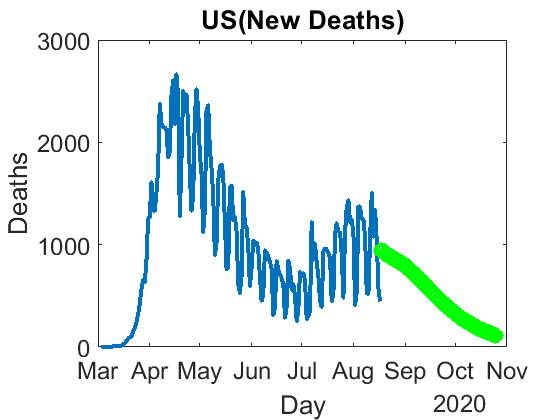

 

xx = find(startsWith(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx(1);
end

eval(['deaths_un = deaths_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_un = infec_un_' num2str(un) '(:, 1:sel_horizon);']);
%eval(['deaths_released_un = deaths_released_un_' num2str(un) '(:, 1:sel_horizon);']);

offset = 40;
trueshow = (offset:size(deaths, 2));
Tx = datetime(2020, 1, 22)+ caldays(trueshow);
plot(Tx(2:end), diff(deaths(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [deaths(cid, T_full) deaths_un(cid, :)];
yy = diff(yy); Tx = Tx(1:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10);
% hold on;
% Tx = datetime(2020, 1, 22)+caldays((T_full:T_full+sel_horizon-1));
% yy = deaths_released_un(cid, :);
% yy = diff(yy); Tx = Tx(2:end);
% plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

title([countries{cid} '(New Deaths)'])
xlabel('Day');
ylabel('Deaths');

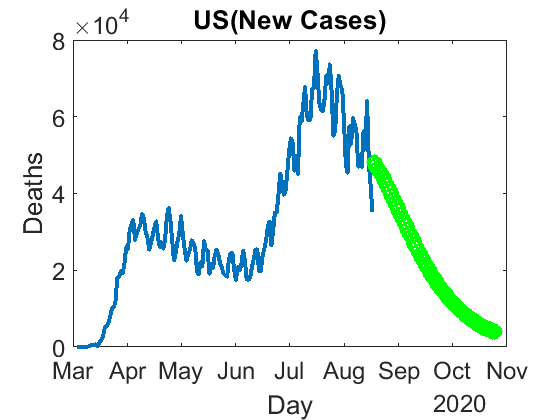


Tx = datetime(2020, 1, 22)+ caldays(offset:T_full);
plot(Tx(2:end), diff(data_4(cid, offset:T_full)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [data_4(cid, T_full) infec_un(cid, :)];
yy = diff(yy); Tx = Tx(1:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10);
% hold on;
% Tx = datetime(2020, 1, 22)+caldays((T_full:T_full+sel_horizon-1));
% yy = deaths_released_un(cid, :);
% yy = diff(yy); Tx = Tx(2:end);
% plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

title([countries{cid} '(New Cases)'])
xlabel('Day');
ylabel('Deaths');

## Scenarios

figure('DefaultAxesFontSize',18);
sel_reg = "US"; % Select a region to predict
un = 20;
sel_horizon = 100

sel_horizon = 100

 

xx = find(startsWith(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx(1)
end

cid = 156


eval(['deaths_un = deaths_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['deaths_released_un = deaths_released_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['deaths_restricted_un = deaths_restricted_un_' num2str(un) '(:, 1:sel_horizon);']);


offset = 60;
trueshow = (offset:size(deaths, 2));
Tx = datetime(2020, 1, 22)+ caldays(trueshow);
yy = diff(deaths(cid, trueshow));
yy = deaths(cid, trueshow);
plot(Tx(1:end), yy, 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [deaths(cid, T_full) deaths_un(cid, :)];
yy = diff(yy);
yy = deaths_un(cid, :);
plot(Tx, yy, 'b', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10);
hold on;

yy = [deaths(cid, T_full) deaths_released_un(cid, :)];
yy = diff(yy);
yy = deaths_released_un(cid, :);
plot(Tx, yy, 'r', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold on;

yy = [deaths(cid, T_full) deaths_restricted_un(cid, :)];
yy = diff(yy);
yy = deaths_restricted_un(cid, :)

yy = 	1.0e+05 *

    1.7144    1.7237    1.7329    1.7419    1.7509    1.7597    1.7685    1.7772    1.7858    1.7944    1.8025    1.8102    1.8172    1.8238    1.8296    1.8348    1.8392    1.8432    1.8468    1.8501    1.8531    1.8558    1.8582    1.8604    1.8623    1.8641    1.8658    1.8672    1.8685    1.8697    1.8708    1.8718    1.8727    1.8735    1.8742    1.8748    1.8754    1.8759    1.8764    1.8768    1.8772    1.8776    1.8779    1.8782    1.8784    1.8787    1.8789    1.8790    1.8792    1.8794


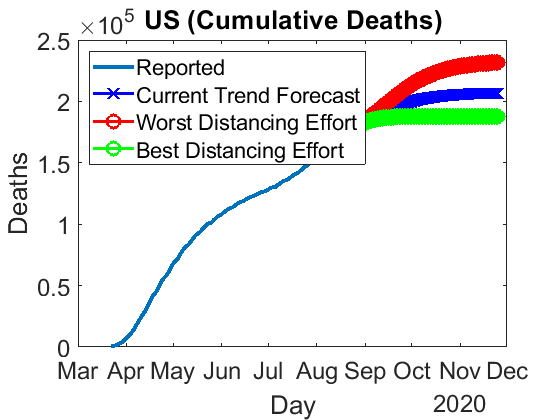

plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

legend({'Reported'; 'Current Trend Forecast'; 'Worst Distancing Effort'; 'Best Distancing Effort'}, 'location', 'northwest');

title([countries{cid} ' (Cumulative Deaths)'])
xlabel('Day');
ylabel('Deaths');

## Case Scenarios

figure('DefaultAxesFontSize',18);
sel_reg = "US"; % Select a region to predict
un = 20;
sel_horizon = 100

sel_horizon = 100

 

xx = find(startsWith(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx(1)
end

cid = 156


eval(['infec_un = infec_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_released_un = infec_released_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['infec_restricted_un = infec_restricted_un_' num2str(un) '(:, 1:sel_horizon);']);


offset = 60;
trueshow = (offset:size(deaths, 2));
Tx = datetime(2020, 1, 22)+ caldays(trueshow);
yy = diff(data_4(cid, trueshow));
yy = data_4(cid, trueshow);
plot(Tx(1:end), yy, 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 22)+caldays((T_full+1:T_full+sel_horizon));
yy = [data_4(cid, T_full) infec_un(cid, :)];
yy = diff(yy);
yy = infec_un(cid, :);
plot(Tx, yy, 'b', 'Marker', 'x', 'LineWidth', 2, 'MarkerSize', 10);
hold on;

yy = [data_4(cid, T_full) infec_released_un(cid, :)];
yy = diff(yy);
yy = infec_released_un(cid, :);
plot(Tx, yy, 'r', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold on;

yy = [data_4(cid, T_full) infec_restricted_un(cid, :)];
yy = diff(yy);
yy = infec_restricted_un(cid, :)

yy = 	1.0e+06 *

    5.4722    5.5043    5.5344    5.5624    5.5882    5.6117    5.6328    5.6511    5.6680    5.6834    5.6974    5.7100    5.7215    5.7317    5.7410    5.7494    5.7569    5.7638    5.7700    5.7756    5.7806    5.7852    5.7893    5.7930    5.7963    5.7994    5.8021    5.8046    5.8068    5.8088    5.8106    5.8122    5.8137    5.8150    5.8162    5.8173    5.8183    5.8192    5.8200    5.8207    5.8213    5.8219    5.8224    5.8229    5.8233    5.8237    5.8241    5.8244    5.8247    5.8249


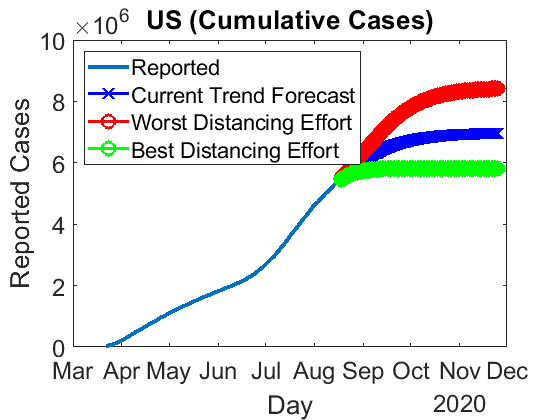

plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); 
hold off;

legend({'Reported'; 'Current Trend Forecast'; 'Worst Distancing Effort'; 'Best Distancing Effort'}, 'location', 'northwest');

title([countries{cid} ' (Cumulative Cases)'])
xlabel('Day');
ylabel('Reported Cases');